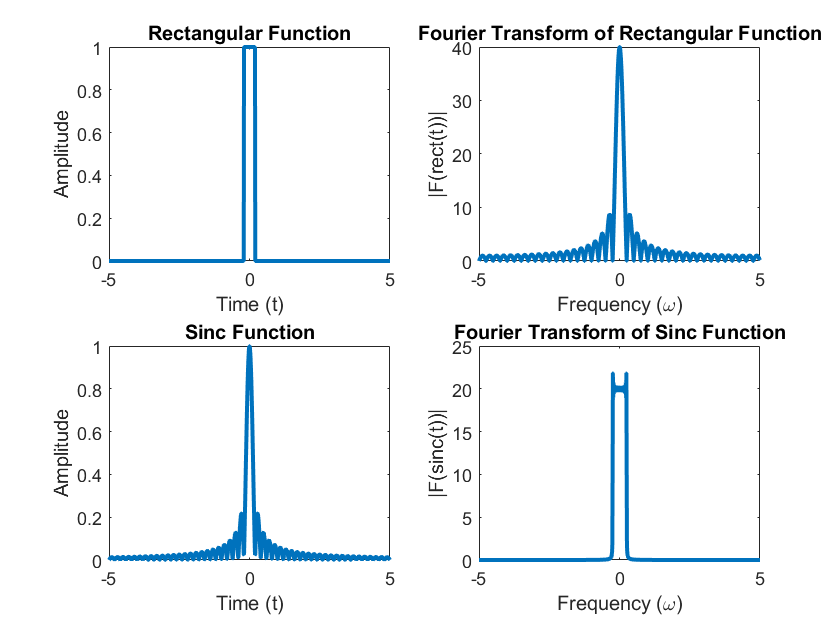

% Duality property demonstration with Rectangular and Sinc functions

% Defining time vector
t = linspace(-5, 5, 1000);

% Rectangular function
rect_function = rectpuls(5*t, 2);

% Fourier transform of Rectangular function
rect_FT = fftshift(fft(rect_function));

% Sinc function
sinc_function = sinc(5*t);

% Fourier transform of Sinc function
sinc_FT = fftshift(fft(sinc_function));

% Plotting the original functions and their Fourier transforms
figure;

% Plotting Rectangular function
subplot(2, 2, 1);
plot(t, rect_function, 'LineWidth', 2);
title('Rectangular Function');
xlabel('Time (t)');
ylabel('Amplitude');

% Plotting Fourier transform of Rectangular function
subplot(2, 2, 2);
plot(t, abs(rect_FT), 'LineWidth', 2);
title('Fourier Transform of Rectangular Function');
xlabel('Frequency (\omega)');
ylabel('|F(rect(t))|');

% Plotting Sinc function
subplot(2, 2, 3);
plot(t, abs(sinc_function), 'LineWidth', 2);
title('Sinc Function');
xlabel('Time (t)');
ylabel('Amplitude');

% Plotting Fourier transform of Sinc function
subplot(2, 2, 4);
plot(t, abs(sinc_FT), 'LineWidth', 2);
title('Fourier Transform of Sinc Function');
xlabel('Frequency (\omega)');
ylabel('|F(sinc(t))|');